# **CNC Milling RUL (IAIA project 1-2)**

Class : Industrial AI & Automation

Instructor : professor Young-keun Kim

Name : Seung-eun Hwang, Min-ung Han

Date : 2023.05.03

#### [ Basic information about dataset ]

- cutter RPM : 10400, 173.333 hz

- feed rate : 1555 mm/min

- Y depth of cut (radial) : 0.125mm

- Z depth of cut (axial) : 0.2mm

- sampling frequency : 50kHz 

- 100,000 ~ 200,000 datas for each file

- total time = 200000 / 50000 = 2 ~ 4s

**Train dataset : C1, C4, C6**

**Test dataset : C2, C3, C5**

## Data load

clear

addpath('../Problem #2/Data');
addpath('../Problem #2/Functions');

loadData = load('c1_features.mat');
c1_feat = loadData.all_features_folder;
loadData = load('pre_c1_features.mat');
pre_c1_feat = loadData.all_features_folder

pre_c1_feat = 315×120 table
     F_x_mean     F_x_std    F_x_rms    F_x_sra    F_x_energy    F_x_ppv    F_x_if    F_x_sf    F_x_cf    F_x_mf    F_x_sk     F_x_kt      F_x_fc      F_x_rmsf      F_x_rvf     F_y_mean     F_y_std    F_y_rms    F_y_sra    F_y_energy    F_y_ppv    F_y_if    F_y_sf    F_y_cf    F_y_mf    F_y_sk     F_y_kt     F_y_fc      F_y_rmsf      F_y_rvf      F_z_mean     F_z_std    F_z_rms    F_z_sra   

loadData = load('pre_c4_features.mat');
pre_c4_feat = loadData.all_features_folder

pre_c4_feat = 315×120 table
    F_x_mean     F_x_std    F_x_rms    F_x_sra    F_x_energy    F_x_ppv    F_x_if    F_x_sf    F_x_cf    F_x_mf     F_x_sk      F_x_kt      F_x_fc      F_x_rmsf      F_x_rvf     F_y_mean     F_y_std    F_y_rms    F_y_sra    F_y_energy    F_y_ppv    F_y_if    F_y_sf    F_y_cf    F_y_mf    F_y_sk     F_y_kt     F_y_fc      F_y_rmsf    F_y_rvf     F_z_mean     F_z_std    F_z_rms    F_z_sra    <

loadData = load('pre_c6_features.mat');
pre_c6_feat = loadData.all_features_folder

pre_c6_feat = 315×120 table
     F_x_mean     F_x_std    F_x_rms    F_x_sra    F_x_energy    F_x_ppv    F_x_if    F_x_sf    F_x_cf    F_x_mf     F_x_sk      F_x_kt      F_x_fc      F_x_rmsf      F_x_rvf      F_y_mean     F_y_std    F_y_rms    F_y_sra    F_y_energy    F_y_ppv    F_y_if    F_y_sf    F_y_cf    F_y_mf     F_y_sk     F_y_kt      F_y_fc      F_y_rmsf      F_y_rvf     F_z_mean     F_z_std    F_z_rms    F_z_sra

## Data Preprocessing

To analyze the data, preprocessing is conducted as a first step. For data such as CNC milling, where various vibration frequencies are mixed, it is necessary to have domain knowledge or perform frequency decomposition.

In order to examine the data belonging to the original signal, we used Empirical Mode Decomposition (EMD) to proceed with the analysis.

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04955   |  SiftMaxRelativeTolerance
      2      |        2     |     0.011781   |  SiftMaxRelativeTolerance
      3      |        2     |     0.060239   |  SiftMaxRelativeTolerance
      4      |        2     |     0.048859   |  SiftMaxRelativeTolerance
      5      |        2     |     0.088623   |  SiftMaxRelativeTolerance
      6      |        2     |     0.059951   |  SiftMaxRelativeTolerance
      7      |        2     |      0.15964   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11085   |  SiftMaxRelativeTolerance
      9      |        2     |      0.18693   |  SiftMaxRelativeTolerance
     10      |        2     |     0.086725   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


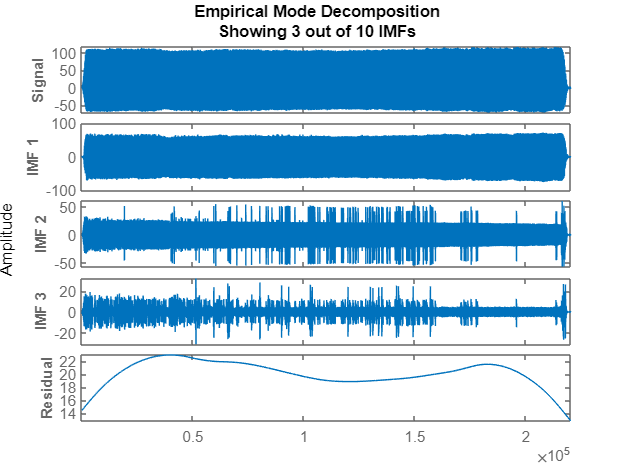

load('c_1_300.mat');
X = matrix_data(:,1);
emd(X,'Interpolation','pchip','Display',1)

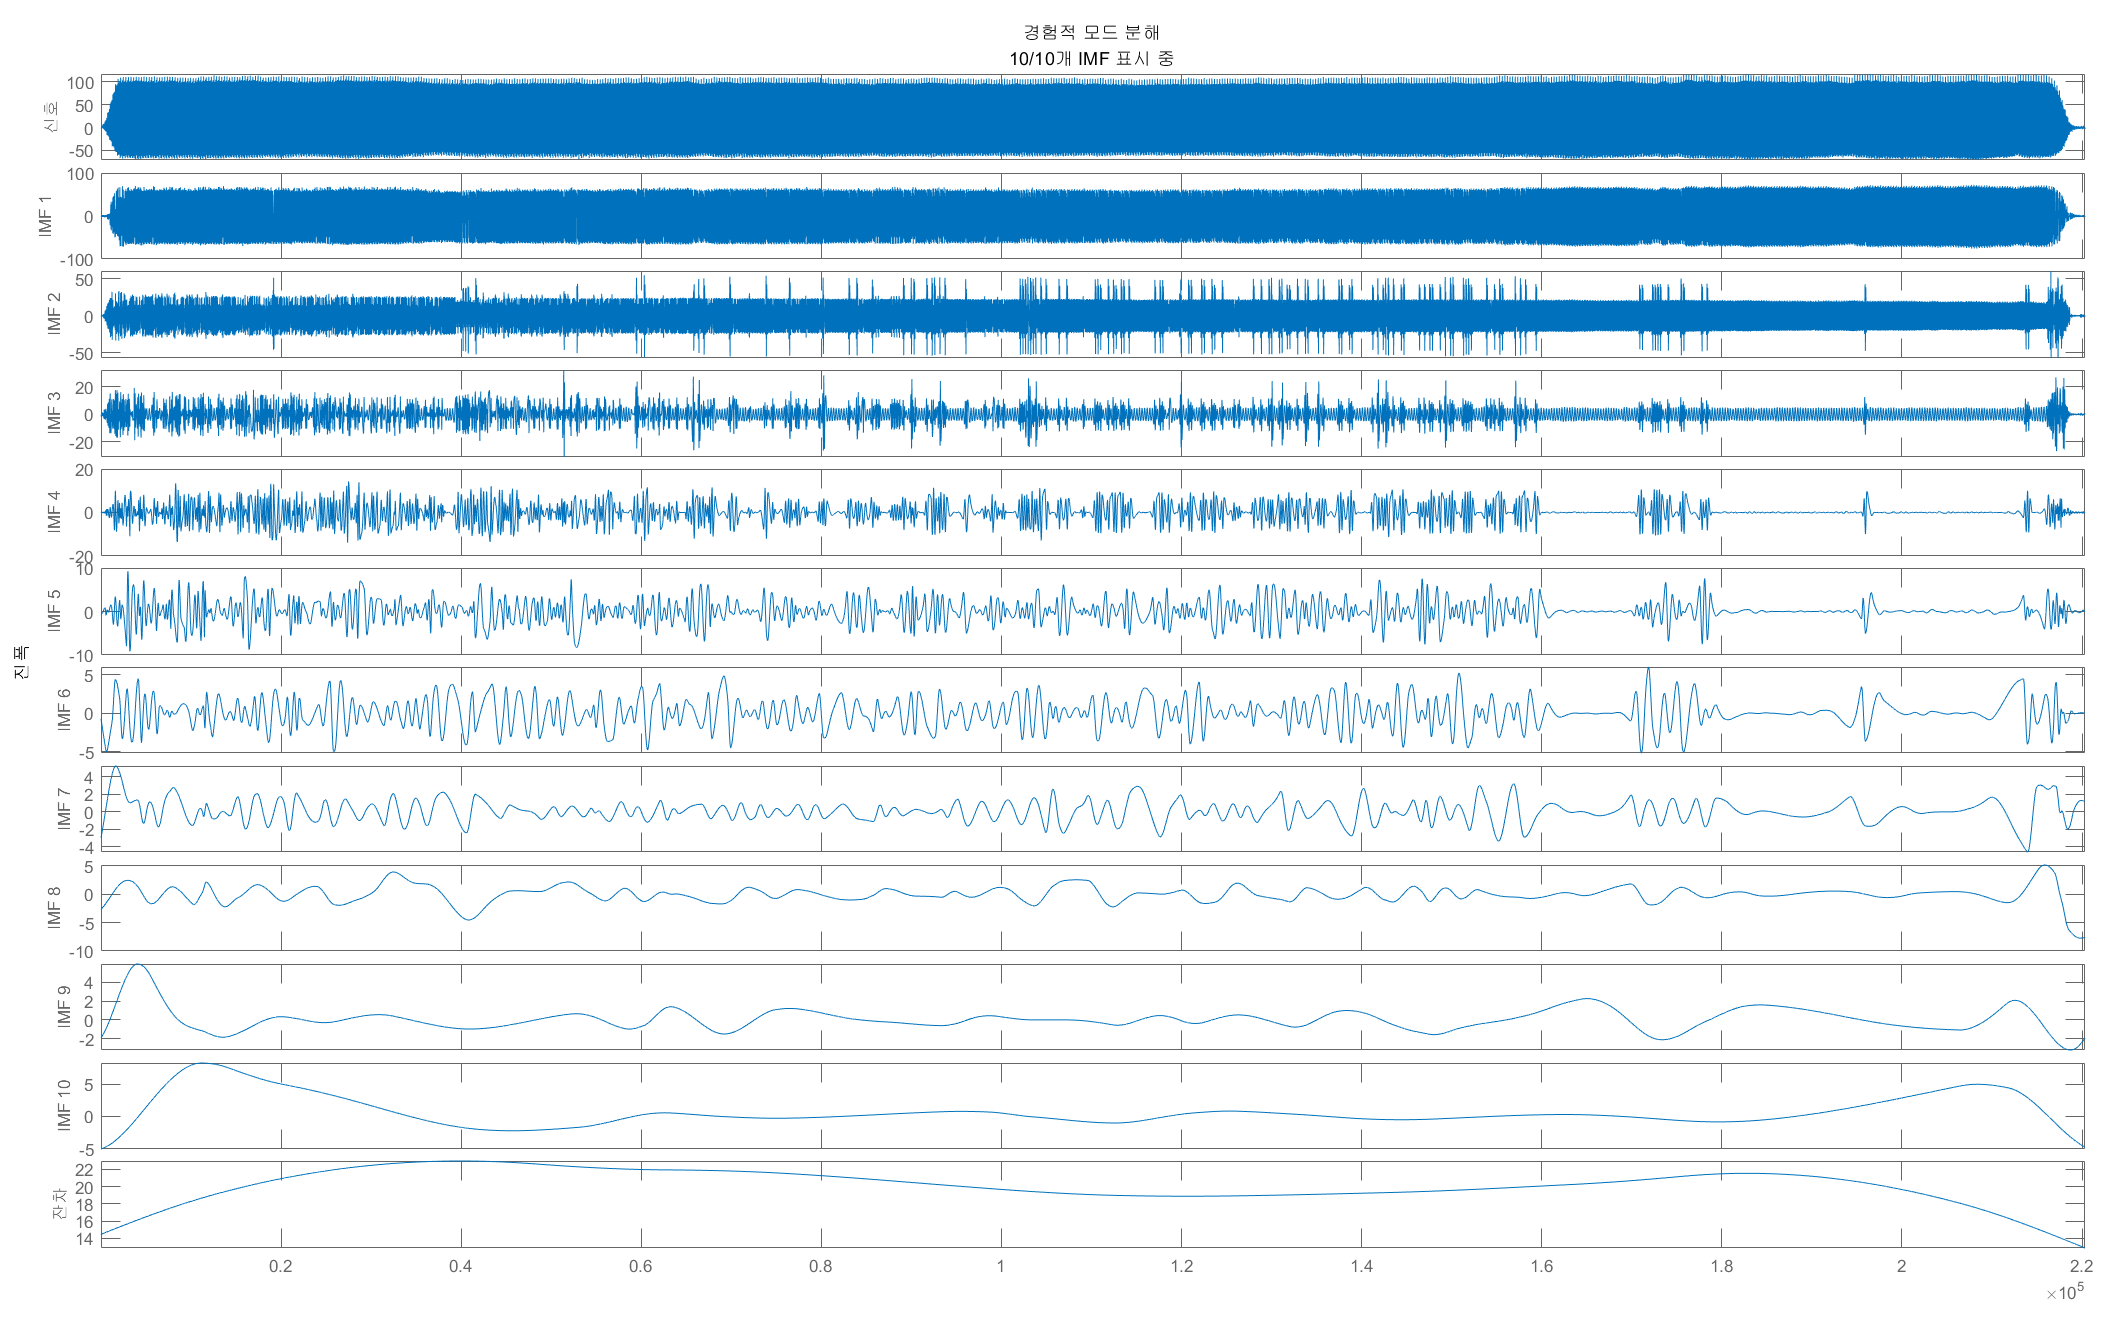

- The above image shows the result of applying EMD to the x-axis force data of C1 at 300. We can observe the decomposition into intrinsic mode functions (IMFs) and the residual based on vibration frequency. As we progress with IMF, the decomposition shifts from high-frequency to low-frequency components. The residual exhibits a trend similar to an offset.

- In CNC milling data, data with slowly varying trends, such as the residual, can be attributed to factors that remain constant or change slowly. For example, it could be due to factors like misalignment of the tool, machine imbalance, or thermal expansion. In this project, the CNC milling PHM data is used to determine the Remaining Useful Life (RUL) by identifying errors in the process caused by cutter wear. Therefore, while the residual may be considered necessary for determining RUL, it was found to interfere with assessing the trend. Therefore, for preprocessing, the data from IMF 1 to IMF 10 were summed together to eliminate the interference caused by the residual.

## Feature Extraction 

**Time Features**

- Mean

- STD

- RMS

- sra (square root average)

- Energy

- peak to peak

- Impulse Factor

- Shape Factor

- Crest Factor

- Marginal(Clearance) Factor

- Skewness

- Kurtosis

**Frequency Features**

- fc

- rmsf

- rvf 

## Result of Preprocessing

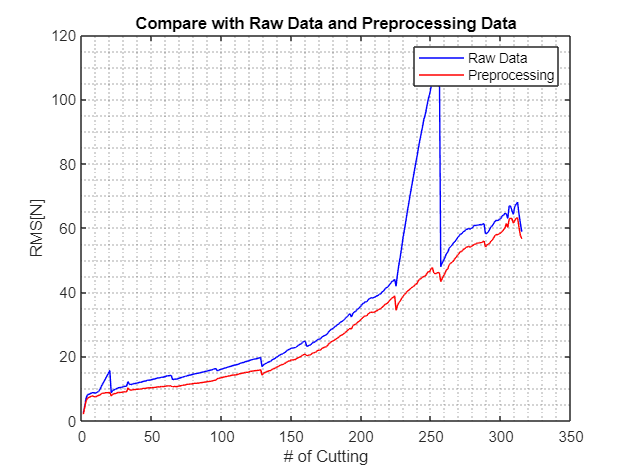

figure;
plot(c1_feat{:,"F_mag_rms"}, 'b-')
hold on;
plot(pre_c1_feat{:,'F_mag_rms'}, 'r-')
hold off;
xlabel('# of Cutting');
ylabel('RMS[N]');
title('Compare with Raw Data and Preprocessing Data');
legend('Raw Data', 'Preprocessing');
grid minor;

## Output label (wear data)

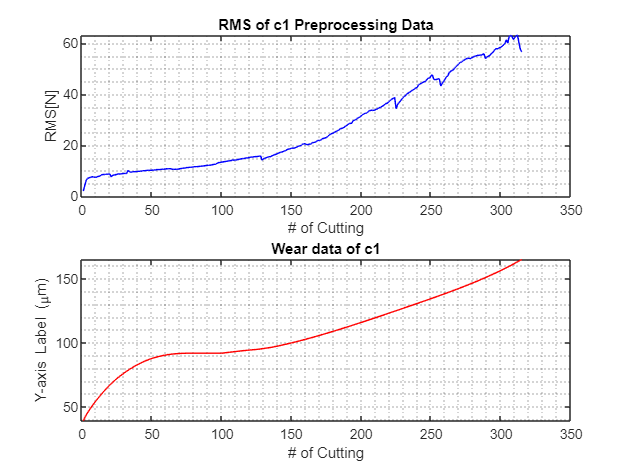

load("fluteValue.mat")
fluteValue = matFile;

figure;
subplot(2,1,1)
plot(pre_c1_feat{:,"F_mag_rms"}, 'b-')
xlabel('# of Cutting');
ylabel('RMS[N]');
title('RMS of c1 Preprocessing Data');
grid minor;

subplot(2,1,2)
plot(fluteValue(:,2), 'r-')
xlabel('# of Cutting');
ylabel('Y-axis Label (\mum)')
title('Wear data of c1');
grid minor;

From the graph, we can observe that as the Root Mean Square (RMS) increases, the average wear value of the three flutes also increases. Based on this, we can conclude that the data exhibits a similar trend according to the degree of cutter wear.

## Postprocessing

To proceed with the Remaining Useful Life (RUL) estimation, the general table was transformed into a Time Table. Then, a moving average window filter was applied to the original features for data post-processing. Since the data sizes were different, normalization was performed using the min-max scaler.

The conversion to Time Table was done using the "conver2timetable.m" function. The "rowTimes" parameter was set as a duration vector, which is in minutes, representing the number of times the processing was conducted in each minute.

Additionally, the wear data was added to the last column of the train data, resulting in a total of 121 columns.

**Train data**

load("c1_timetable.mat")
load("c4_timetable.mat")
load("c1_timetable_smooth.mat")
load("c4_timetable_smooth.mat")

**Test data**

load("c3_array.mat")
load("c5_array.mat")

**smoothing data c1**

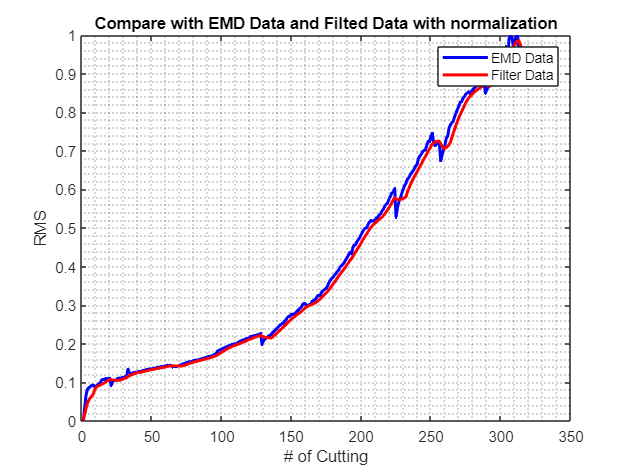

figure;
plot(c1_timetable{:,"F_mag_rms"}, 'b-', LineWidth=2)
hold on;
plot(c1_timetable_smooth{:,'F_mag_rms'}, 'r-', LineWidth=2)
hold off;
xlabel('# of Cutting');
ylabel('RMS');
title('Compare with EMD Data and Filted Data with normalization');
legend('EMD Data', 'Filter Data');
grid minor;

**smoothing data c4**

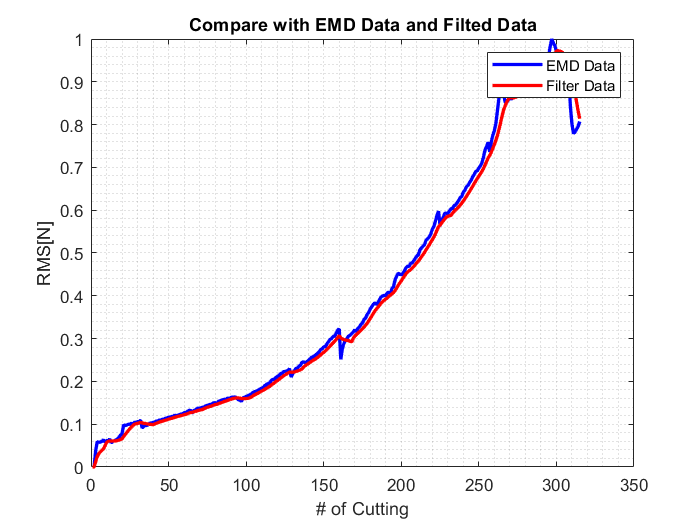

figure;
plot(c4_timetable{:,"F_mag_rms"}, 'b-', LineWidth=2)
hold on;
plot(c4_timetable_smooth{:,'F_mag_rms'}, 'r-', LineWidth=2)
hold off;
xlabel('# of Cutting');
ylabel('RMS[N]');
title('Compare with EMD Data and Filted Data');
legend('EMD Data', 'Filter Data');
grid minor;

## Compare with wear and all Features

To determine if the data features exhibit a similar pattern to the wear value, the corr function was used to identify features that are correlated with the wear value in advance.

% Calculate correlations and apply threshold
corr_threshold = 0.92;

c1_correlation = corr(c1_timetable_smooth{:, 1:120}, c1_timetable_smooth{:,'Wear'});
c4_correlation = corr(c4_timetable_smooth{:, 1:120}, c4_timetable_smooth{:,'Wear'});

% Find selected variable names for each table
c1_selected_vars = c1_timetable.Properties.VariableNames(abs(c1_correlation) > corr_threshold)

c1_selected_vars = 1×66 cell array
    {'F_x_std'}    {'F_x_rms'}    {'F_x_sra'}    {'F_x_ppv'}    {'F_x_if'}    {'F_x_cf'}    {'F_x_mf'}    {'F_x_fc'}    {'F_x_rmsf'}    {'F_x_rvf'}    {'F_y_std'}    {'F_y_rms'}    {'F_y_sra'}    {'F_y_energy'}    {'F_y_ppv'}    {'F_y_fc'}    {'F_y_rmsf'}    {'F_y_rvf'}    {'F_z_std'}    {'F_z_rms'}    {'F_z_sra'}    {'F_z_energy'}    {'F_z_ppv'}    {'F_z_fc'}    {'F_z_rmsf'}    {'F_z_rvf'}    {'g_x_std'}    {'g_x_rms'}    {'g_x_sra'}    {'g_x_ppv'}    {'g_x_fc'}    {'g_x_rmsf'}    {'g_y_std'}    {'g_y_rms'}    {'g_y_sra'}    {'g_y_energy'}    {'g_y_ppv'}    {'g_y_sk'}    {'g_y_fc'}    {'g_y_rmsf'}    {'g_y_rvf'}    {'g_z_std'}    {'g_z_rms'}    {'g_z_sra'}    {'g_z_energy'}    {'g_z_ppv'}    {'g_z_fc'}    {'g_z_rmsf'}    {'g_z_rvf'}    {'F_mag_mean'}    {'F_mag_std'}    {'F_mag_rms'}    {'F_mag_sra'}    {'F_mag_energy'}    {'F_mag_ppv'}    {'F_mag_fc'}    {'F_mag_rmsf'}    {'F_mag_rvf'}    {'g_mag_mean'}    {'g_mag_rms'}    {'g_mag_sra'}    {'g_mag_e

c4_selected_vars = c4_timetable.Properties.VariableNames(abs(c4_correlation) > corr_threshold)

c4_selected_vars = 1×64 cell array
    {'F_x_std'}    {'F_x_rms'}    {'F_x_sra'}    {'F_x_energy'}    {'F_x_ppv'}    {'F_x_fc'}    {'F_x_rmsf'}    {'F_x_rvf'}    {'F_y_std'}    {'F_y_rms'}    {'F_y_sra'}    {'F_y_energy'}    {'F_y_ppv'}    {'F_y_fc'}    {'F_y_rmsf'}    {'F_y_rvf'}    {'F_z_std'}    {'F_z_rms'}    {'F_z_sra'}    {'F_z_energy'}    {'F_z_ppv'}    {'F_z_rmsf'}    {'F_z_rvf'}    {'g_x_std'}    {'g_x_rms'}    {'g_x_sra'}    {'g_x_energy'}    {'g_x_ppv'}    {'g_x_fc'}    {'g_x_rmsf'}    {'g_x_rvf'}    {'g_y_std'}    {'g_y_rms'}    {'g_y_sra'}    {'g_y_energy'}    {'g_y_ppv'}    {'g_y_fc'}    {'g_y_rmsf'}    {'g_y_rvf'}    {'g_z_std'}    {'g_z_rms'}    {'g_z_sra'}    {'g_z_energy'}    {'g_z_ppv'}    {'g_z_fc'}    {'g_z_rmsf'}    {'g_z_rvf'}    {'F_mag_mean'}    {'F_mag_std'}    {'F_mag_rms'}    {'F_mag_sra'}    {'F_mag_energy'}    {'F_mag_ppv'}    {'F_mag_fc'}    {'F_mag_rmsf'}    {'F_mag_rvf'}    {'g_mag_mean'}    {'g_mag_rms'}    {'g_mag_sra'}    {'g_mag_energy'}    {'g_mag_

% Find the common variable names across the selected features of the three tables
common_selected_vars = intersect(c1_selected_vars, c4_selected_vars);
% Select the common features from the original tables using the common variable names
c1_common_selected_features = c1_timetable_smooth(:, common_selected_vars);
c4_common_selected_features = c4_timetable_smooth(:, common_selected_vars);

## Training Data for c1

breakpoint = 300;
c1_trainData = c1_common_selected_features(1:breakpoint, common_selected_vars);
c1_RULData = c1_common_selected_features(:, common_selected_vars);

## Feature Importance Ranking

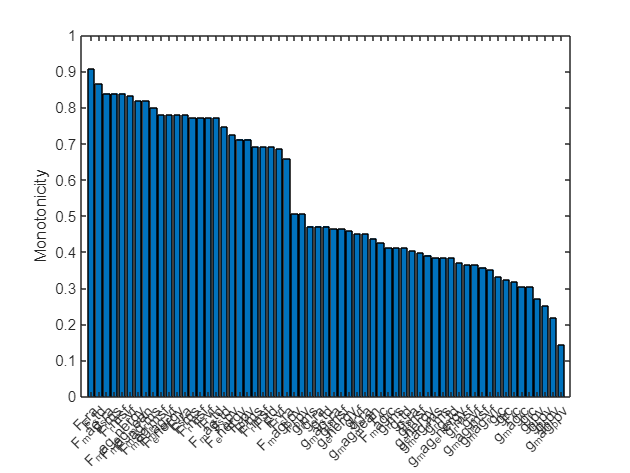

featureImportance = monotonicity(c1_trainData, 'WindowSize', 0);
helperSortedBarPlot(featureImportance, 'Monotonicity');

## Feature selction with monotonicity

c1_trainIdx = featureImportance{:,:} >= 0.82;

c1_trainSelected = c1_trainData(:, c1_trainIdx);
c1_featureSelected = c1_RULData(:, c1_trainIdx)

c1_featureSelected = 315×6 timetable
     Time     F_mag_sra    F_x_rms     F_x_rmsf    F_x_rvf      F_x_sra     F_x_std 
    ______    _________    ________    ________    ________    _________    ________

    1 min            0            0           0           0            0           0
    2 min     0.015496     0.010503    0.007852    0.007892    0.0096136    0.010354
    3 min     0.031206     0.019435    0.015778    0.015834     0.017221    0.019134
    4 min      0.04242     0.025409    0.021226    0.021289     0.022082    0.025032
    5 min     0.049951     0.028941    0.024426     0.02449     0.025259    0.028527
    6 min     0.055453     

## Feature Reduction (PCA)

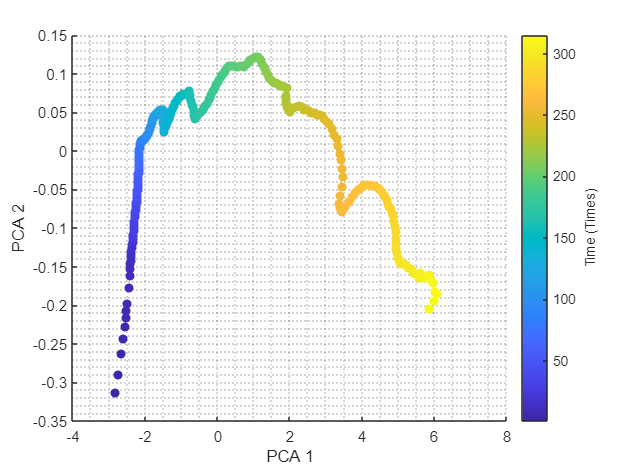

meanTrain = mean(c1_trainSelected{:,:});
sdTrain = std(c1_trainSelected{:,:});
trainDataNormalized = (c1_trainSelected{:,:} - meanTrain)./sdTrain;
coef = pca(trainDataNormalized);

c1_PCA1 = (c1_featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
c1_PCA2 = (c1_featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);

timeUnit = 'Times';

figure
numData = size(c1_featureSelected, 1);
scatter(c1_PCA1, c1_PCA2, [], 1:numData, 'filled')
xlabel('PCA 1')
ylabel('PCA 2')
cbar = colorbar;
ylabel(cbar, ['Time (' timeUnit ')'])
grid minor;

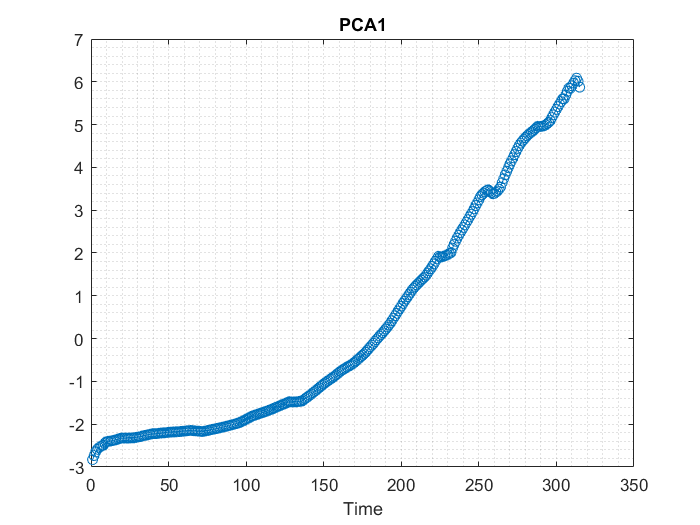

figure
plot(c1_PCA1, '-o')
xlabel('Time')
title('PCA1')
grid minor;

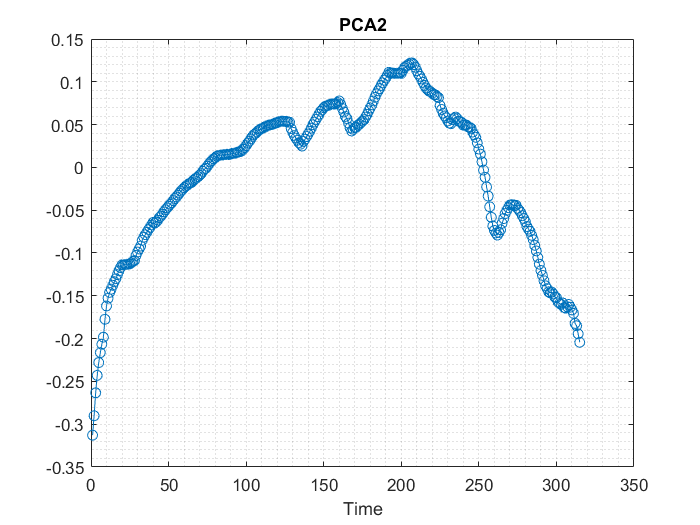

figure
plot(c1_PCA2, '-o')
xlabel('Time')
title('PCA2')
grid minor;

c1_healthIndicator = c1_PCA1;

Visualize the health indicator.

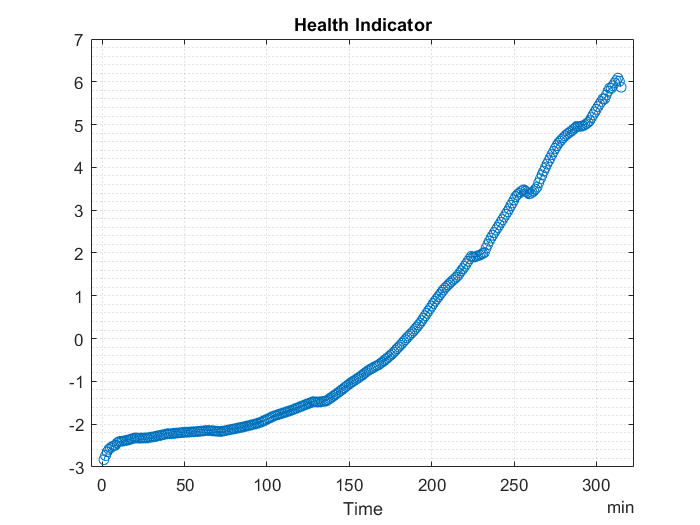

figure
plot(c1_featureSelected.Time, c1_healthIndicator, '-o')
xlabel('Time')
title('Health Indicator')
grid minor;

## Fit Exponential Degradation Models for Remaining Useful Life (RUL) Estimation

- Exponential degradation model was generated to confirm tendency

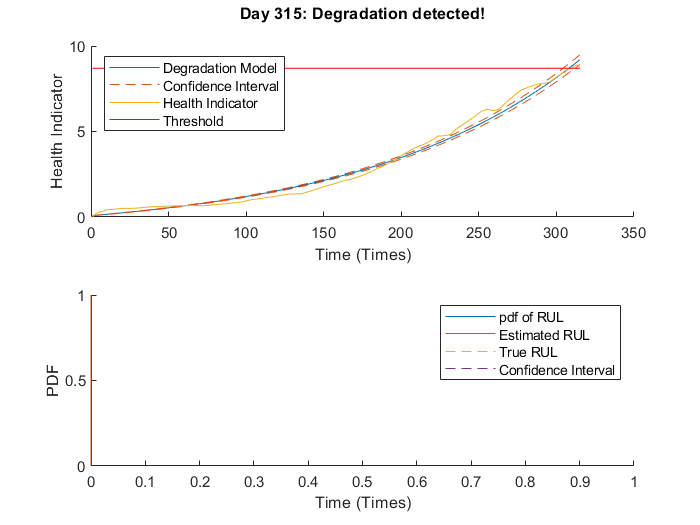

c1_healthIndicator = c1_healthIndicator - c1_healthIndicator(1);
threshold = c1_healthIndicator(end);
c1_mdl_EXD = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold/(threshold + 1))^2, ...
    'SlopeDetectionLevel', 0.05);

% Keep records at each iteration
totalDay = length(c1_healthIndicator);
c1_estRULs = zeros(totalDay, 1);
c1_trueRULs = zeros(totalDay, 1);
c1_CIRULs = zeros(totalDay, 2);
c1_pdfRULs = cell(totalDay, 1);

% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);

for currentDay = 1:totalDay
    
    % Update model parameter posterior distribution
    update(c1_mdl_EXD, [currentDay c1_healthIndicator(currentDay)])
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(c1_mdl_EXD, ...
                                         [currentDay c1_healthIndicator(currentDay)], ...
                                         threshold);
    trueRUL = totalDay - currentDay + 1;
    
    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, c1_healthIndicator, c1_mdl_EXD, threshold, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
    
    % Keep prediction results
    c1_estRULs(currentDay) = estRUL;
    c1_trueRULs(currentDay) = trueRUL;
    c1_CIRULs(currentDay, :) = CIRUL;
    c1_pdfRULs{currentDay} = pdfRUL;
    
    
    % Pause 0.1 seconds to make the animation visible
    pause(0.001)
end

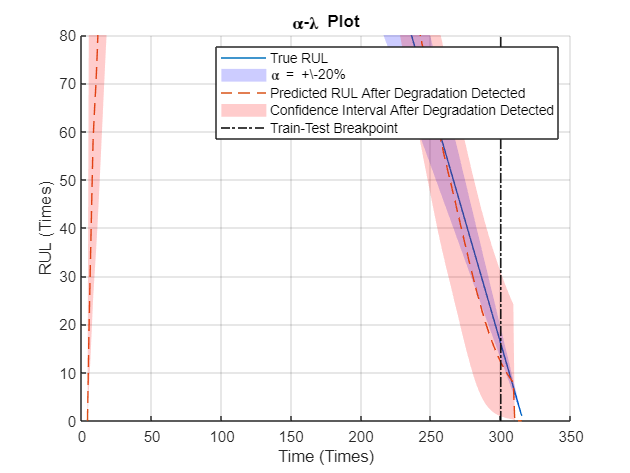

alpha = 0.2; % +- 20%
detectTime = c1_mdl_EXD.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, c1_trueRULs, c1_estRULs, c1_CIRULs, ...
    c1_pdfRULs, detectTime, breakpoint, timeUnit);
title('\alpha-\lambda Plot')

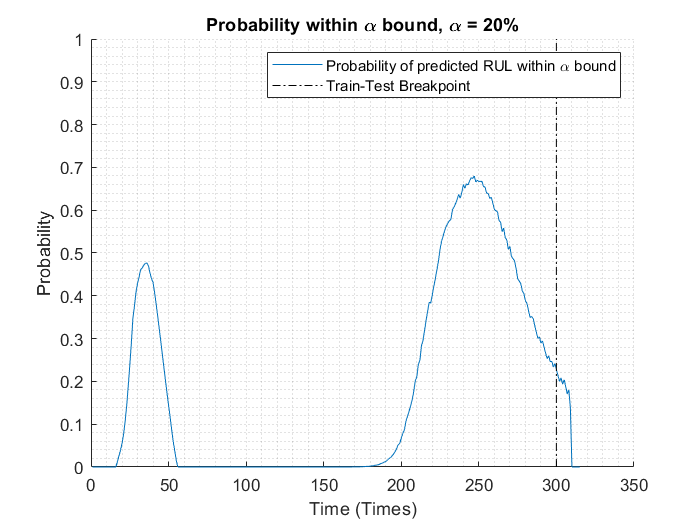

figure
t = 1:totalDay;
hold on
plot(t, prob)
plot([breakpoint breakpoint], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])
grid minor;

## Trian c4

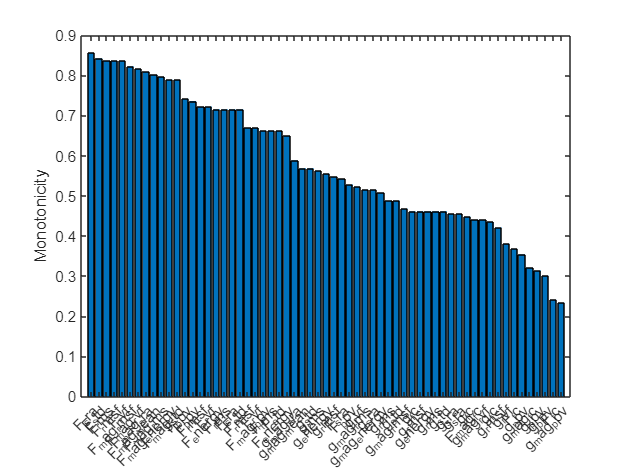

c4_trainData = c4_common_selected_features(1:breakpoint, common_selected_vars);
c4_RULData = c4_common_selected_features(:, common_selected_vars);

featureImportance = monotonicity(c4_trainData, 'WindowSize', 0);
helperSortedBarPlot(featureImportance, 'Monotonicity');

c4_trainIdx = featureImportance{:,:} >= 0.82;

c4_trainSelected = c4_trainData(:, c4_trainIdx);
c4_featureSelected = c4_RULData(:, c4_trainIdx)

c4_featureSelected = 315×6 timetable
     Time     F_mag_rmsf     F_x_rms     F_x_rmsf      F_x_rvf      F_x_sra     F_x_std 
    ______    __________    _________    _________    _________    _________    ________

    1 min             0             0            0            0            0           0
    2 min             0             0            0            0            0           0
    3 min      0.010437     0.0058922    0.0043707    0.0043755    0.0054018    0.005899
    4 min      0.020819      0.011483    0.0090093    0.0090213     0.010602    0.011489
    5 min      0.026201      0.013722     0.010425     0.010438     0.012876    0.013674
    6 mi

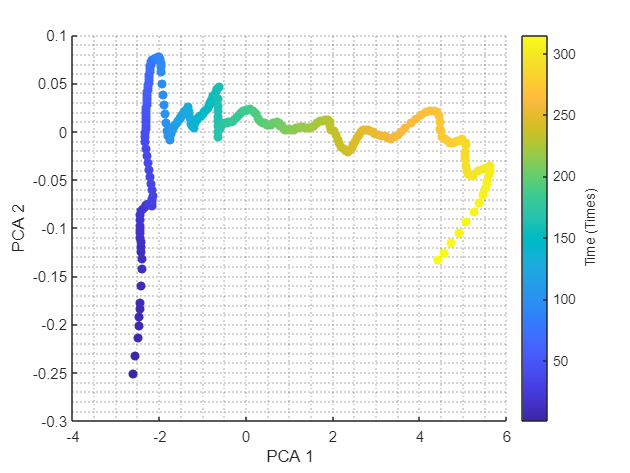

meanTrain = mean(c4_trainSelected{:,:});
sdTrain = std(c4_trainSelected{:,:});
trainDataNormalized = (c4_trainSelected{:,:} - meanTrain)./sdTrain;
coef = pca(trainDataNormalized);

c4_PCA1 = (c4_featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
c4_PCA2 = (c4_featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);

timeUnit = 'Times';

figure
numData = size(c4_featureSelected, 1);
scatter(c4_PCA1, c4_PCA2, [], 1:numData, 'filled')
xlabel('PCA 1')
ylabel('PCA 2')
cbar = colorbar;
ylabel(cbar, ['Time (' timeUnit ')'])
grid minor;

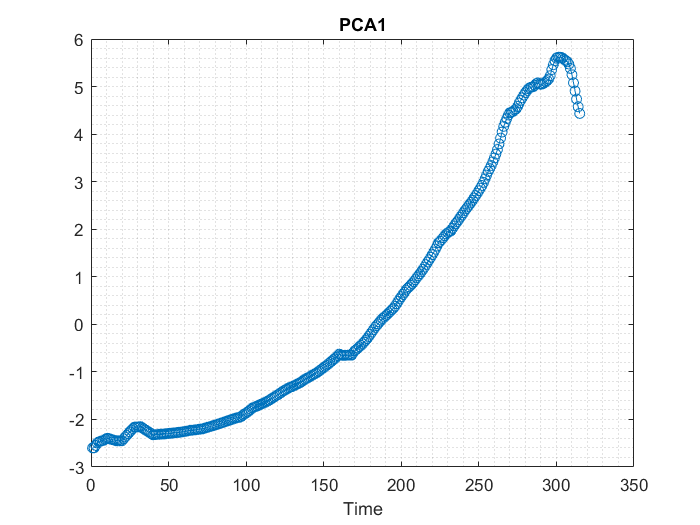

figure
plot(c4_PCA1, '-o')
xlabel('Time')
title('PCA1')
grid minor;

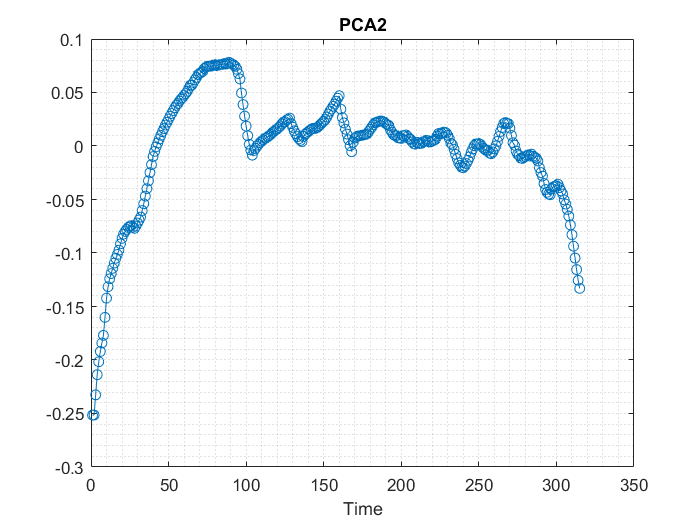

figure
plot(c4_PCA2, '-o')
xlabel('Time')
title('PCA2')
grid minor;

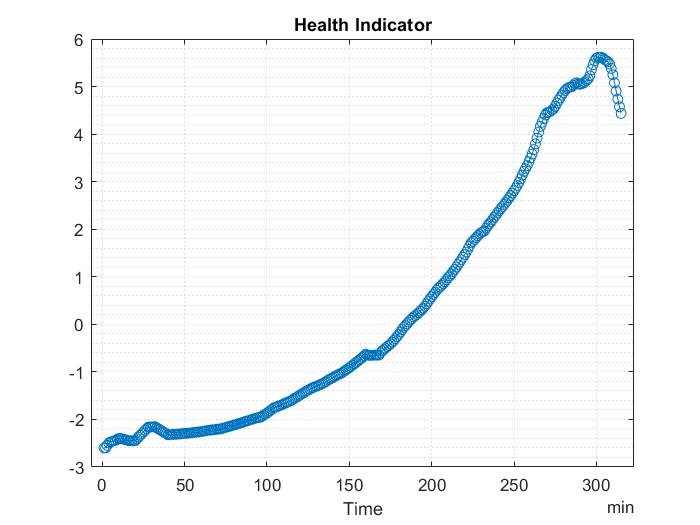

c4_healthIndicator = c4_PCA1;
figure
plot(c4_featureSelected.Time, c4_healthIndicator, '-o')
xlabel('Time')
title('Health Indicator')
grid minor;

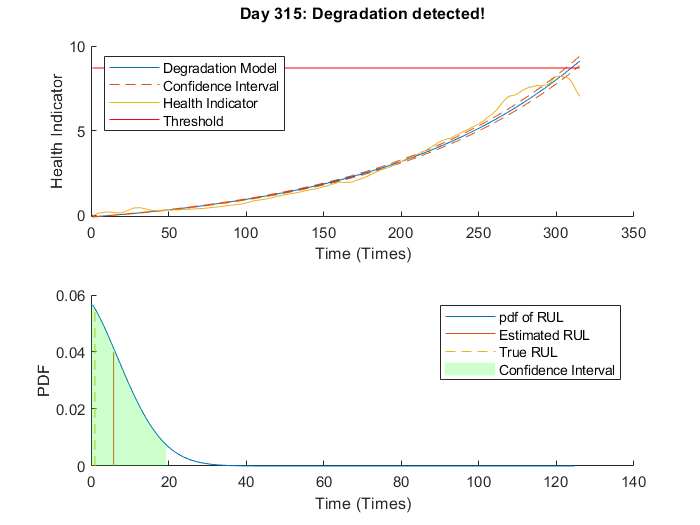

c4_healthIndicator = c4_healthIndicator - c4_healthIndicator(1);

% Keep records at each iteration
totalDay = length(c4_healthIndicator);
c4_estRULs = zeros(totalDay, 1);
c4_trueRULs = zeros(totalDay, 1);
c4_CIRULs = zeros(totalDay, 2);
c4_pdfRULs = cell(totalDay, 1);

% Create figures and axes for plot updating
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);

c4_mdl_EXD = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold/(threshold + 1))^2, ...
    'SlopeDetectionLevel', 0.05);

for currentDay = 1:totalDay
    
    % Update model parameter posterior distribution
    update(c4_mdl_EXD, [currentDay c4_healthIndicator(currentDay)])
    
    % Predict Remaining Useful Life
    [estRUL, CIRUL, pdfRUL] = predictRUL(c4_mdl_EXD, ...
                                         [currentDay c4_healthIndicator(currentDay)], ...
                                         threshold);
    trueRUL = totalDay - currentDay + 1;
    
    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, c4_healthIndicator, c4_mdl_EXD, threshold, timeUnit);
    helperPlotRUL(ax2, trueRUL, estRUL, CIRUL, pdfRUL, timeUnit)
    
    % Keep prediction results
    c4_estRULs(currentDay) = estRUL;
    c4_trueRULs(currentDay) = trueRUL;
    c4_CIRULs(currentDay, :) = CIRUL;
    c4_pdfRULs{currentDay} = pdfRUL;
    
    
    % Pause 0.1 seconds to make the animation visible
    pause(0.01)
end

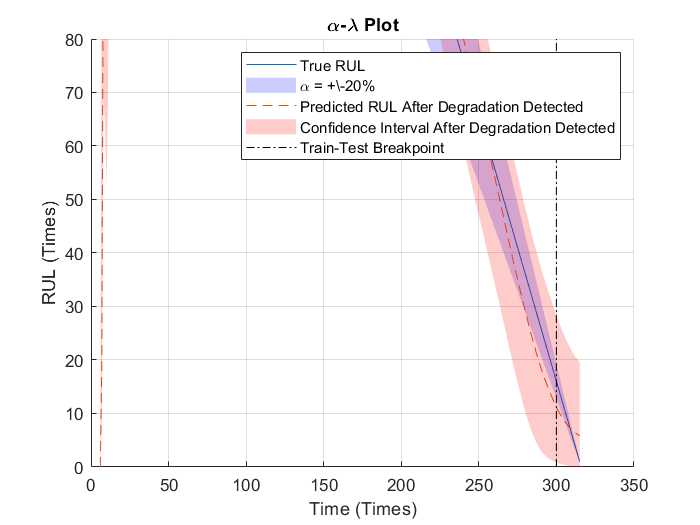


alpha = 0.2; % +- 20%
detectTime = c4_mdl_EXD.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, c4_trueRULs, c4_estRULs, c4_CIRULs, ...
    c4_pdfRULs, detectTime, breakpoint, timeUnit);
title('\alpha-\lambda Plot')

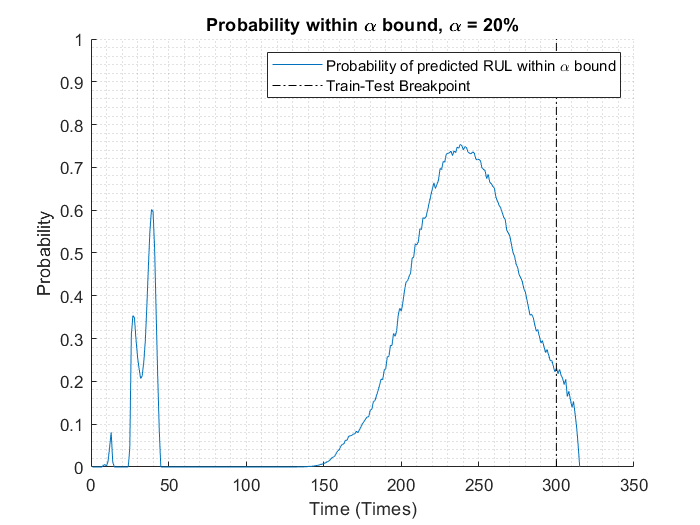

figure
t = 1:totalDay;
hold on
plot(t, prob)
plot([breakpoint breakpoint], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])
grid minor;

## Regression for wear value predict

c1_inputData = timetable2table(c1_timetable_smooth(:,1:end)); 
c1_inputData = table2array(c1_inputData(:,common_selected_vars));
c1_inputData = c1_inputData(:,c1_trainIdx);
c1_outputData = timetable2table(c1_timetable(:,end));
c1_outputData = table2array(c1_outputData(:,2));
% Fit linear regression model
c1_mdl = fitlm(c1_inputData, c1_outputData);

c4_inputData = timetable2table(c4_timetable_smooth(:,1:end)); 
c4_inputData = table2array(c4_inputData(:,common_selected_vars));
c4_inputData = c4_inputData(:,c4_trainIdx);
c4_outputData = timetable2table(c4_timetable(:,end));
c4_outputData = table2array(c4_outputData(:,2));
% Fit linear regression model
c4_mdl = fitlm(c4_inputData, c4_outputData);

**c1 mdl**

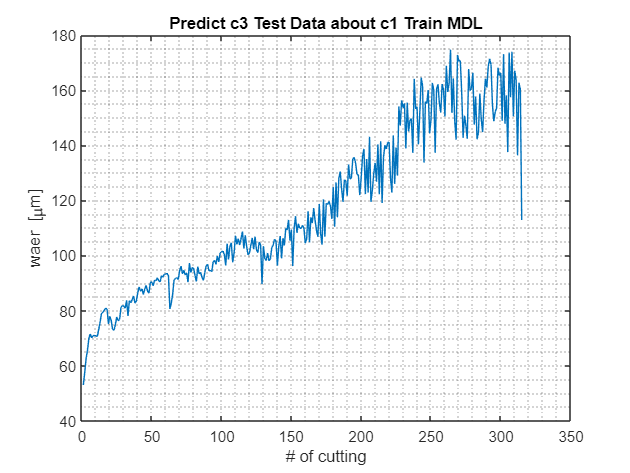

c1_c3_testInputData = c3_array(:, common_selected_vars);
c1_c3_testInputData = c1_c3_testInputData(:,c1_trainIdx);
c1_c3_testInputData = table2array(c1_c3_testInputData);
c1_c3_predictedOutput= predict(c1_mdl, c1_c3_testInputData);
t = linspace(1, 315, 315);
plot(t, c1_c3_predictedOutput);
% hold on
% plot(t, c1_outputData)
% hold off
xlabel('# of cutting')
ylabel('waer [\mum]');
title('Predict c3 Test Data about c1 Train MDL')
grid minor;

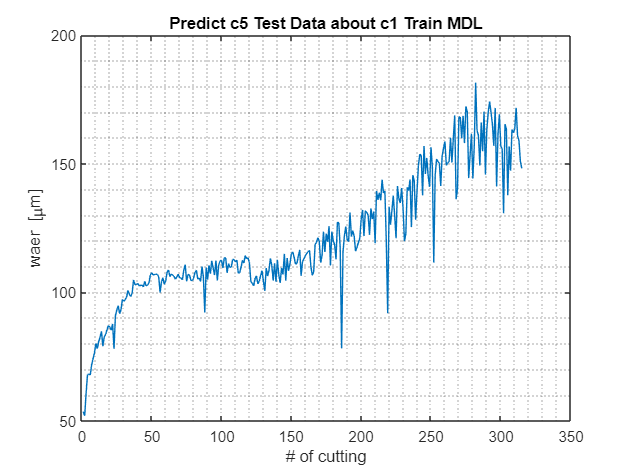

c1_c5_testInputData = c5_array(:, common_selected_vars);
c1_c5_testInputData = c1_c5_testInputData(:,c1_trainIdx);
c1_c5_testInputData = table2array(c1_c5_testInputData);
c1_c5_predictedOutput= predict(c1_mdl, c1_c5_testInputData);
t = linspace(1, 315, 315);
plot(t, c1_c5_predictedOutput);
xlabel('# of cutting')
ylabel('waer [\mum]');
title('Predict c5 Test Data about c1 Train MDL')
grid minor;

**c4 mdl**

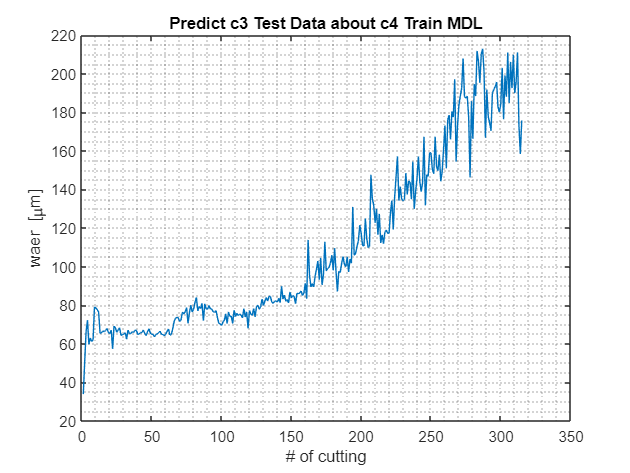

% c4
c4_c3_testInputData = c3_array(:, common_selected_vars);
c4_c3_testInputData = c4_c3_testInputData(:,c4_trainIdx);
c4_c3_testInputData = table2array(c4_c3_testInputData);
c4_c3_predictedOutput= predict(c4_mdl, c4_c3_testInputData);
t = linspace(1, 315, 315);
plot(t, c4_c3_predictedOutput);
% hold on
% plot(t, c4_outputData)
% hold off

xlabel('# of cutting')
ylabel('waer [\mum]');
title('Predict c3 Test Data about c4 Train MDL')
grid minor;

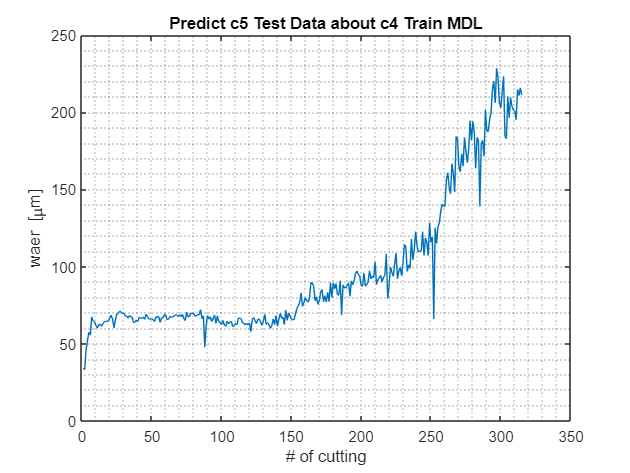

% c4
c4_c5_testInputData = c5_array(:, common_selected_vars);
c4_c5_testInputData = c4_c5_testInputData(:,c4_trainIdx);
c4_c5_testInputData = table2array(c4_c5_testInputData);
c4_c5_predictedOutput= predict(c4_mdl, c4_c5_testInputData);
t = linspace(1, 315, 315);
plot(t, c4_c5_predictedOutput);
xlabel('# of cutting')
ylabel('waer [\mum]');
title('Predict c5 Test Data about c4 Train MDL')
grid minor;

## Ensemble model generation

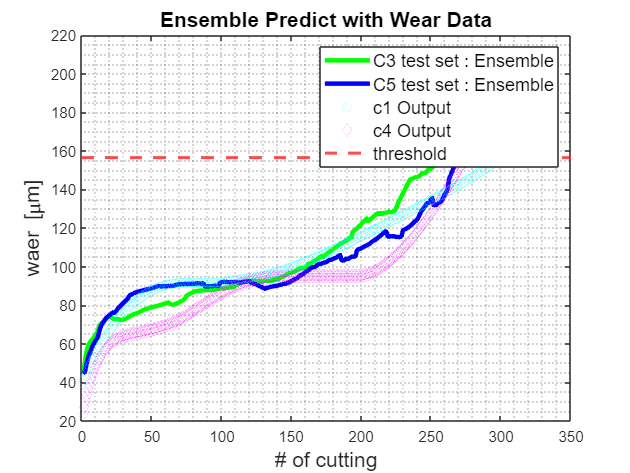

filter_num = 10;

c3_ensamble = c1_c3_predictedOutput * 0.6 + c4_c3_predictedOutput * 0.4;
c3_ensamble = array2table(c3_ensamble);
c3_ensamble_smooth = varfun(@(X) movmean(X, [filter_num 0]), c3_ensamble(:,1));

c3_ensamble = table2array(c3_ensamble);
c3_ensamble_smooth = table2array(c3_ensamble_smooth);

c5_ensamble = c1_c5_predictedOutput * 0.6 + c4_c5_predictedOutput * 0.4;
c5_ensamble = array2table(c5_ensamble);
c5_ensamble_smooth = varfun(@(X) movmean(X, [filter_num 0]), c5_ensamble(:,1));
c5_ensamble = table2array(c5_ensamble);
c5_ensamble_smooth = table2array(c5_ensamble_smooth);


plot(t, c3_ensamble_smooth, 'g-', LineWidth=3 );
hold on
plot(t, c5_ensamble_smooth, 'b-' ,LineWidth=3 );
hold on
plot(t, c1_outputData, 'co', LineWidth = 0.1);
hold on
plot(t, c4_outputData, 'md', LineWidth=0.1);

hold off
xlabel('# of cutting', fontSize = 14);
ylabel('waer [\mum]', fontSize = 14);
title('Ensemble Predict with Wear Data', fontSize = 14)
yline(156.495, 'r--', LineWidth=2)
legend('C3 test set : Ensemble', 'C5 test set : Ensemble', 'c1 Output',  'c4 Output','threshold' ,fontSize = 12)
% ylim([0 180])
grid minor;

## Ensemble model generation

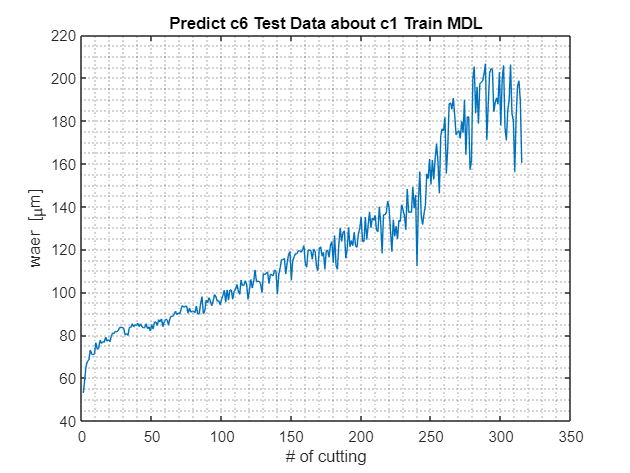

load("c6_array.mat")

c1_c6_testInputData = c6_array(:, common_selected_vars);
c1_c6_testInputData = c1_c6_testInputData(:,c1_trainIdx);
c1_c6_testInputData = table2array(c1_c6_testInputData);
c1_c6_predictedOutput= predict(c1_mdl, c1_c6_testInputData);
t = linspace(1, 315, 315);
plot(t, c1_c6_predictedOutput);
% hold on
% plot(t, c1_outputData)
% hold off
xlabel('# of cutting')
ylabel('waer [\mum]');
title('Predict c6 Test Data about c1 Train MDL')
grid minor;

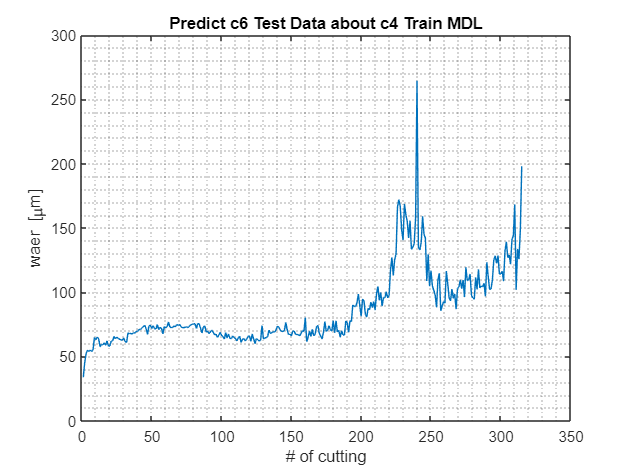


% c4
c4_c6_testInputData = c6_array(:, common_selected_vars);
c4_c6_testInputData = c4_c6_testInputData(:,c4_trainIdx);
c4_c6_testInputData = table2array(c4_c6_testInputData);
c4_c6_predictedOutput= predict(c4_mdl, c4_c6_testInputData);
t = linspace(1, 315, 315);
plot(t, c4_c6_predictedOutput);
% hold on
% plot(t, c4_outputData)
% hold off

xlabel('# of cutting')
ylabel('waer [\mum]');
title('Predict c6 Test Data about c4 Train MDL')
grid minor;

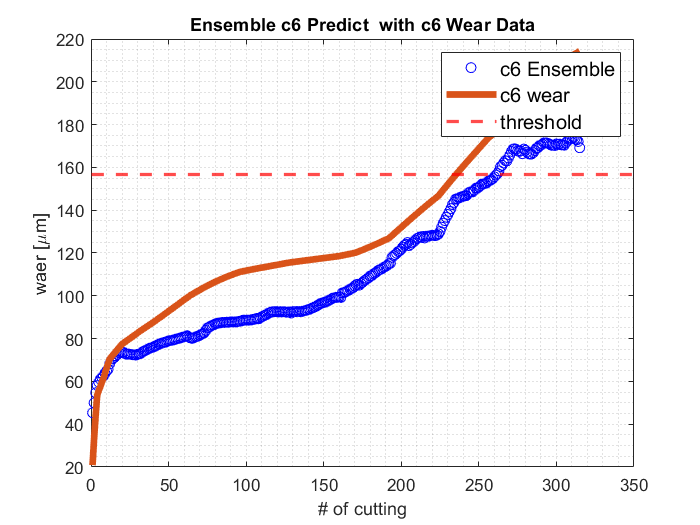

c6_ensamble = c1_c6_predictedOutput * 0.6 + c4_c6_predictedOutput * 0.4;
c6_ensamble = array2table(c6_ensamble);
c6_ensamble_smooth = varfun(@(X) movmean(X, [filter_num 0]), c6_ensamble(:,1));
c6_array = table2array(c6_array);

c6_ensamble_array = table2array(c6_ensamble);
sum = 0;

figure;
plot(t, c3_ensamble_smooth, 'bo',LineWidth = 0.6);
hold on
plot(t, c6_array(:, end), LineWidth = 4)
hold off
xlabel('# of cutting')
ylabel('waer [\mum]');
title('Ensemble c6 Predict  with c6 Wear Data')
yline(156.495, 'r--', LineWidth=2)
legend('c6 Ensemble', 'c6 wear', 'threshold', fontSize = 12)
grid minor;

## Discussion and anlaysis

### 1. Used data 

First, the given data consists of force and vibration data in the X, Y, and Z directions. Additionally, considering the possibility of meaningful features, data related to the magnitude of force and vibration were also included. Subsequently, the extraction of characteristics in the time and frequency domains for each data was performed.Since there is a sufficient amount of data, C1 and C4 are selected as the training data to create the model. After generating the model using C1 and C4, it will be applied to C6 for practical performance analysis. Based on the validation results, the model will be further applied to the test set for evaluation.

### 2. Preprocessing

In the preprocessing stage, the Empirical Mode Decomposition (EMD) technique was applied. EMD is an empirical mode decomposition method that decomposes the original signal into multiple frequency components and analyzes the noise components. By removing unnecessary components, it aims to restore the original signal.

Here, the original signal was decomposed into several frequency components called Intrinsic Mode Functions (IMFs) using EMD. Fast Fourier Transform (FFT) was then applied to analyze the frequency components present in each IMF signal. Although FFT is typically used to remove high-frequency noise, no significant noisy components were found in this case.

Therefore, each frequency component was extracted, and the residual, which was deemed irrelevant, was excluded. The remaining IMF signals were then combined to reconstruct the original signal, following the EMD preprocessing technique.

Afterwards, since the data contained many outliers, a smoothing process was applied for further preprocessing. Finally, normalization was performed before proceeding with feature extraction.

### 3. Correlation & Monotonicity

First, the training data includes a wear file that numerically represents the degree of wear for each cutter. Therefore, an initial analysis was conducted to examine the correlation between each feature and the wear file. Only the features that exceeded a certain threshold were selected in the first step. Then, by comparing the monotonicity, additional features that exceeded a certain threshold were extracted. This process resulted in the final selection of features required for each model generation. Since each feature initially had a high correlation, it is essential to go through this process to select the feature that can maximize performance.

### 4. Exponential degradation model

Afterwards, an exponential degradation model is created using the selected features, and principal component analysis (PCA) is performed. The PCA model, also known as the health indicator, is chosen as the final model. By examining the distribution plot, it becomes possible to visually observe when the failure occurs. Based on the generated model, it is determined that the cutter completely fails at approximately the 305th cutting cycle. By applying this model to the test set, it is possible to validate the trend of the model. Additionally, verification of the model's trend is possible through plots such as the alpha plot. Although there may be some outliers in the early stages that are considered as minor failures, they have minimal impact on the overall analysis.

### 5. Linear regression model

After validating the model's soundness through trend verification, it is necessary to create a linear regression model to predict the actual degree of cutter wear. The selected feature data is used to generate the model. To prevent overfitting, C1 and C4 were used as the training set. Considering that individual data contains a large amount of data, forming an ensemble model with these two data sets was deemed sufficient to prevent overfitting. The ensemble model is represented as a linear combination of predictions from individual models, with weights assigned to each model's predictions on the test set. Then, before applying the desired prediction model, it is necessary to validate the difference between the actual values of wear from the wear file in C6 and the predicted values when applying the model. Based on the results, it was determined that there is no issue with using the generated model, and it was applied. Finally, the model was applied to the test sets C3 and C5 to output the predicted values, demonstrating the approximate cutting cycles at which wear is expected to occur.